## Test Image 1

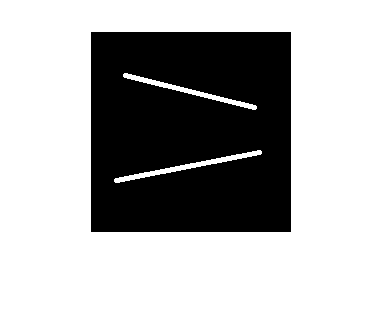

%Load image into BW
image = imread('houghTestImages/image1.png'); 
bw = imbinarize(rgb2gray(image));
[numRows, numCols] = size(bw);
    
figure();
imshow(bw)

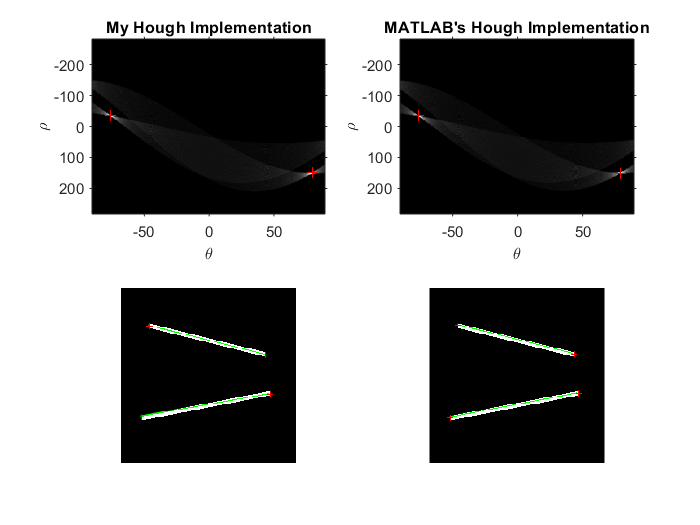


[myHoughMatrix, myTheta, myRho] = myHough(bw);
[H, T, R] = hough(bw);

figure();
subplot(2,2,1);
myPeaks  = myHoughPeaks(myHoughMatrix, 2, 80);
imshow(uint8(myHoughMatrix),[0 max(max(myHoughMatrix))],'XData', myTheta, 'YData', myRho, 'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
title("My Hough Implementation");
axis on, axis normal, hold on;
hold on; plot(myTheta(myPeaks(:, 2)), myRho(myPeaks(:, 1)), 'r+'); hold off;

subplot(2,2,2);
P = houghpeaks(H, 2);
imshow(uint8(H),[0 max(max(H))],'XData', T, 'YData', R, 'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
title("MATLAB's Hough Implementation");
axis on, axis normal, hold on;
hold on; plot(T(P(:, 2)), R(P(:, 1)), 'r+'); hold off;

subplot(2,2,3);
myLines = myHoughLines(bw, myTheta, myRho, myPeaks);
myMarkedImage = insertShape(256 * bw, 'line', myLines, 'LineWidth',2,'Color','green');
myMarkedImage = insertMarker(myMarkedImage, [[myLines(:,1); myLines(:,3)] [myLines(:,2); myLines(:,4)]], 'Size',3,'Color','red');
imshow(myMarkedImage);

subplot(2,2,4);
lines = myHoughLines(bw, T, R, P);
markedImage = insertShape(256 * bw, 'line', lines, 'LineWidth',2,'Color','green');
markedImage = insertMarker(markedImage, [[lines(:,1); lines(:,3)] [lines(:,2); lines(:,4)]], 'Size',3,'Color','red');
imshow(markedImage);

## Test Image 2

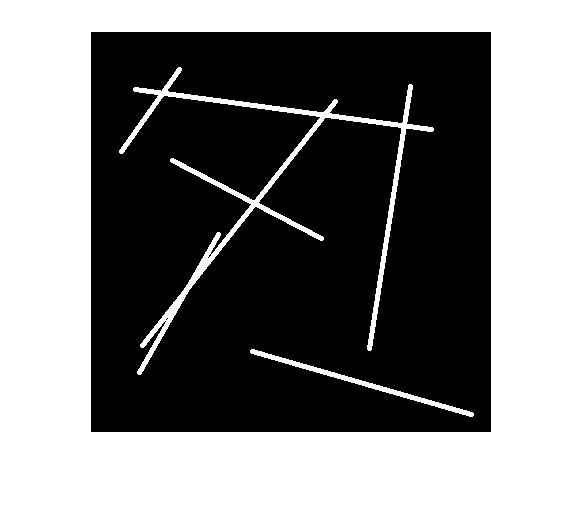

%Load image into BW
image = imread('houghTestImages/image2.png'); 
bw = imbinarize(rgb2gray(image));
[numRows, numCols] = size(bw);
    
figure();
imshow(bw)

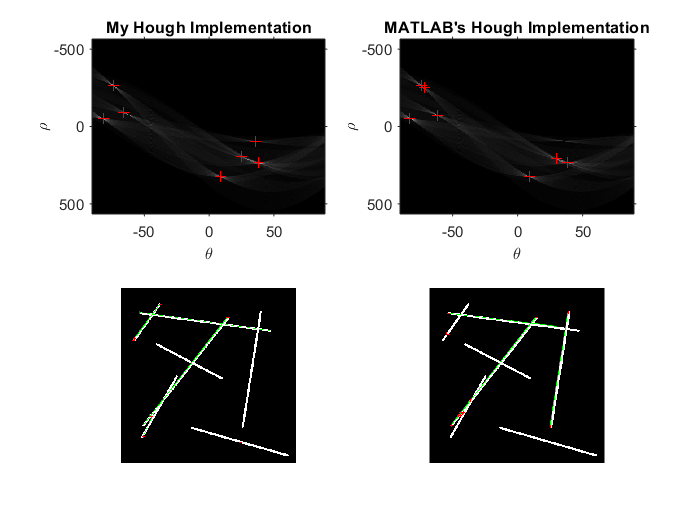


[myHoughMatrix, myTheta, myRho] = myHough(bw);
[H, T, R] = hough(bw);

figure();
subplot(2,2,1);
myPeaks  = myHoughPeaks(myHoughMatrix, 7, 80);
imshow(uint8(myHoughMatrix),[0 max(max(myHoughMatrix))],'XData', myTheta, 'YData', myRho, 'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
title("My Hough Implementation");
axis on, axis normal, hold on;
hold on; plot(myTheta(myPeaks(:, 2)), myRho(myPeaks(:, 1)), 'r+'); hold off;

subplot(2,2,2);
P = houghpeaks(H, 7);
imshow(uint8(H),[0 max(max(H))],'XData', T, 'YData', R, 'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
title("MATLAB's Hough Implementation");
axis on, axis normal, hold on;
hold on; plot(T(P(:, 2)), R(P(:, 1)), 'r+'); hold off;

subplot(2,2,3);
myLines = myHoughLines(bw, myTheta, myRho, myPeaks);
myMarkedImage = insertShape(256 * bw, 'line', myLines, 'LineWidth',2,'Color','green');
myMarkedImage = insertMarker(myMarkedImage, [[myLines(:,1); myLines(:,3)] [myLines(:,2); myLines(:,4)]], 'Size',3,'Color','red');
imshow(myMarkedImage);

subplot(2,2,4);
lines = myHoughLines(bw, T, R, P);
markedImage = insertShape(256 * bw, 'line', lines, 'LineWidth',2,'Color','green');
markedImage = insertMarker(markedImage, [[lines(:,1); lines(:,3)] [lines(:,2); lines(:,4)]], 'Size',3,'Color','red');
imshow(markedImage);

## Test Image 3

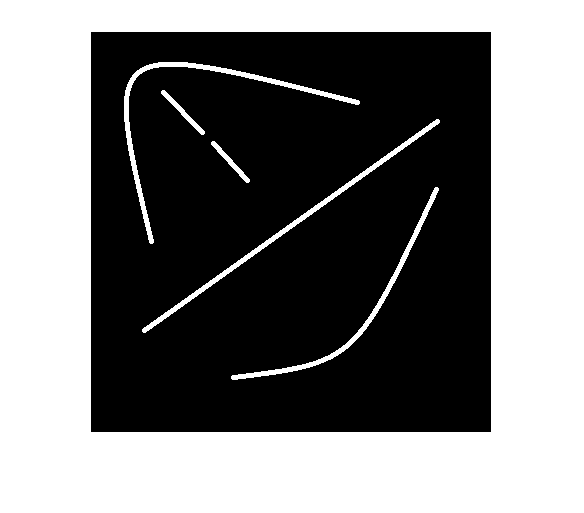

%Load image into BW
image = imread('houghTestImages/image3.png'); 
bw = imbinarize(rgb2gray(image));
[numRows, numCols] = size(bw);
    
figure();
imshow(bw)

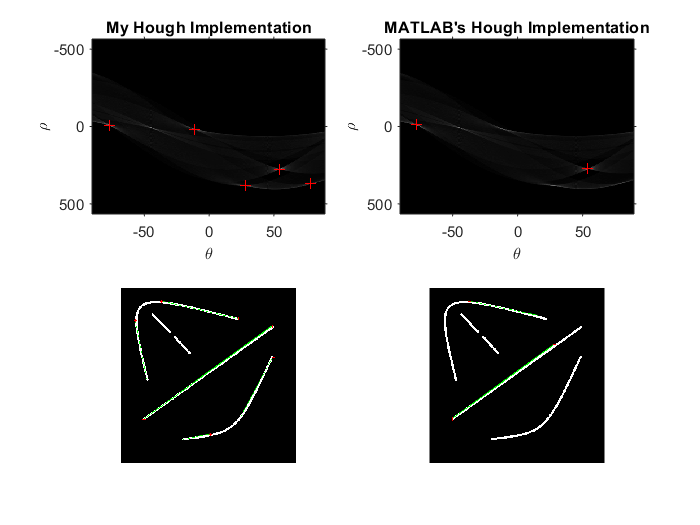


[myHoughMatrix, myTheta, myRho] = myHough(bw);
[H, T, R] = hough(bw);

figure();
subplot(2,2,1);
myPeaks  = myHoughPeaks(myHoughMatrix, 5, 80);
imshow(uint8(myHoughMatrix),[0 max(max(myHoughMatrix))],'XData', myTheta, 'YData', myRho, 'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
title("My Hough Implementation");
axis on, axis normal, hold on;
hold on; plot(myTheta(myPeaks(:, 2)), myRho(myPeaks(:, 1)), 'r+'); hold off;

subplot(2,2,2);
P = houghpeaks(H, 5);
imshow(uint8(H),[0 max(max(H))],'XData', T, 'YData', R, 'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
title("MATLAB's Hough Implementation");
axis on, axis normal, hold on;
hold on; plot(T(P(:, 2)), R(P(:, 1)), 'r+'); hold off;

subplot(2,2,3);
myLines = myHoughLines(bw, myTheta, myRho, myPeaks);
myMarkedImage = insertShape(256 * bw, 'line', myLines, 'LineWidth',2,'Color','green');
myMarkedImage = insertMarker(myMarkedImage, [[myLines(:,1); myLines(:,3)] [myLines(:,2); myLines(:,4)]], 'Size',3,'Color','red');
imshow(myMarkedImage);

subplot(2,2,4);
lines = myHoughLines(bw, T, R, P);
markedImage = insertShape(256 * bw, 'line', lines, 'LineWidth',2,'Color','green');
markedImage = insertMarker(markedImage, [[lines(:,1); lines(:,3)] [lines(:,2); lines(:,4)]], 'Size',3,'Color','red');
imshow(markedImage);